
%#ok<*CLALL>

clear all;clc 

% Sim settings. 
maxSpeed = 1E-1; 
timeStep = 4; 

% Initial states. 
initialStates = [-1; 0; 1; 0]; 

% Position constraints. 
areaBounds = [-1; 1; -1; 1]*50; 

% TPBVP test time span input. 
tspan = 0 : 1E-2 : timeStep; 

% Initial guess. 
% guess = [ ...
%     initialStates; ...
%     (initialStates(1)-initialStates(3)); ...
%     (initialStates(2)-initialStates(4)); ...
%     -(initialStates(1)-initialStates(3)); ...
%     -(initialStates(2)-initialStates(4)); ...
%     zeros(4, 1)]; 
guess = 1E-1*ones(8, 1); 
guess(1:4) = [ ...
    initialStates(3); ...
    initialStates(4); ...
    initialStates(3)+timeStep*maxSpeed; 
    initialStates(4)+timeStep*maxSpeed]; 
guess(5) = (guess(1)-guess(3)); 
guess(6) = (guess(2)-guess(4)); 
guess(7) = -(guess(1)-guess(3)); 
guess(8) = -(guess(2)-guess(4)); 
disp(guess); 

    1.0000
         0
    1.4000
    0.4000
   -0.4000
   -0.4000
    0.4000
    0.4000



solGuess = bvpinit(tspan, guess); 
options = bvpset("Stats", "on"); 
sol = bvp4c( ...
    @(t, y) eqns(t, y, maxSpeed, areaBounds), ...
    @(y_a, y_b) boundaryConditions(y_a, y_b, initialStates), ...
    solGuess, options); 

The solution was obtained on a mesh of 401 points.
The maximum residual is  1.829e-14. 
There were 16881 calls to the ODE function. 
There were 72 calls to the BC function. 


solGuess = bvpinit(tspan, sol.y(:, end)); 
sol = bvp4c( ...
    @(t, y) eqns(t, y, maxSpeed, areaBounds), ...
    @(y_a, y_b) boundaryConditions(y_a, y_b, initialStates), ...
    solGuess, options); 

The solution was obtained on a mesh of 401 points.
The maximum residual is  3.097e-12. 
There were 10449 calls to the ODE function. 
There were 47 calls to the BC function. 


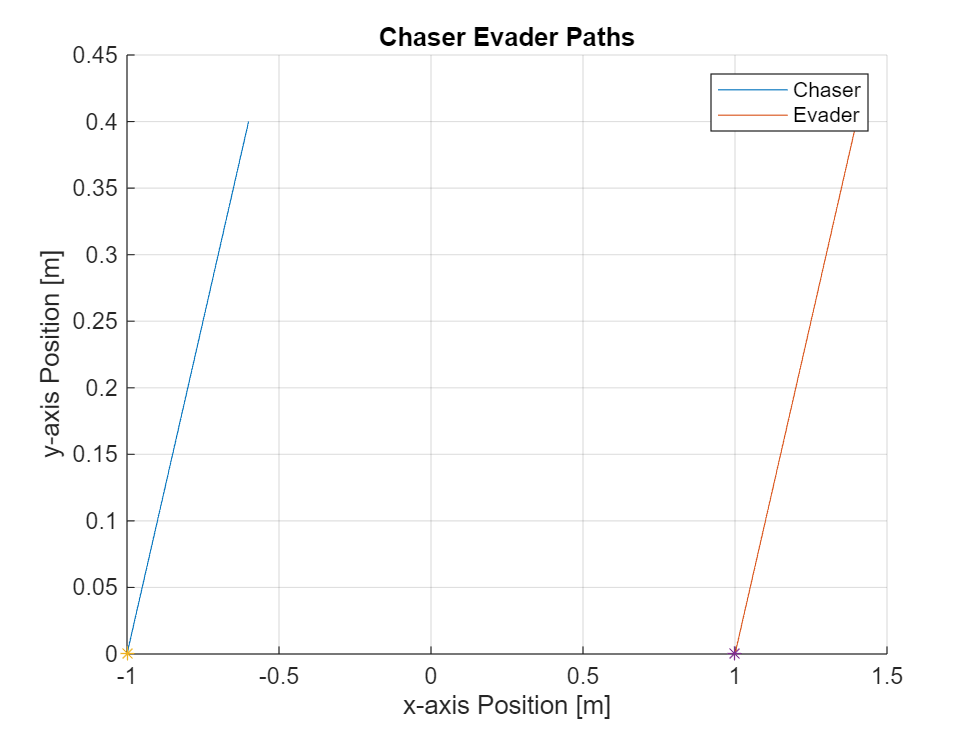

tspan = sol.x; 
y = sol.y; 
chaserPath = y(1:2, :); 
evaderPath = y(3:4, :); 

clf; 
hold on; 
grid on; 
plot(chaserPath(1, :), chaserPath(2, :), evaderPath(1, :), evaderPath(2, :)); 
plot(chaserPath(1, 1), chaserPath(2, 1), "*"); 
plot(evaderPath(1, 1), evaderPath(2, 1), "*"); 
title("Chaser Evader Paths"); 
xlabel("x-axis Position [m]"); 
ylabel("y-axis Position [m]"); 
legend("Chaser", "Evader"); 
% axis([-2 1 -1 1.6]); 
hold off;  

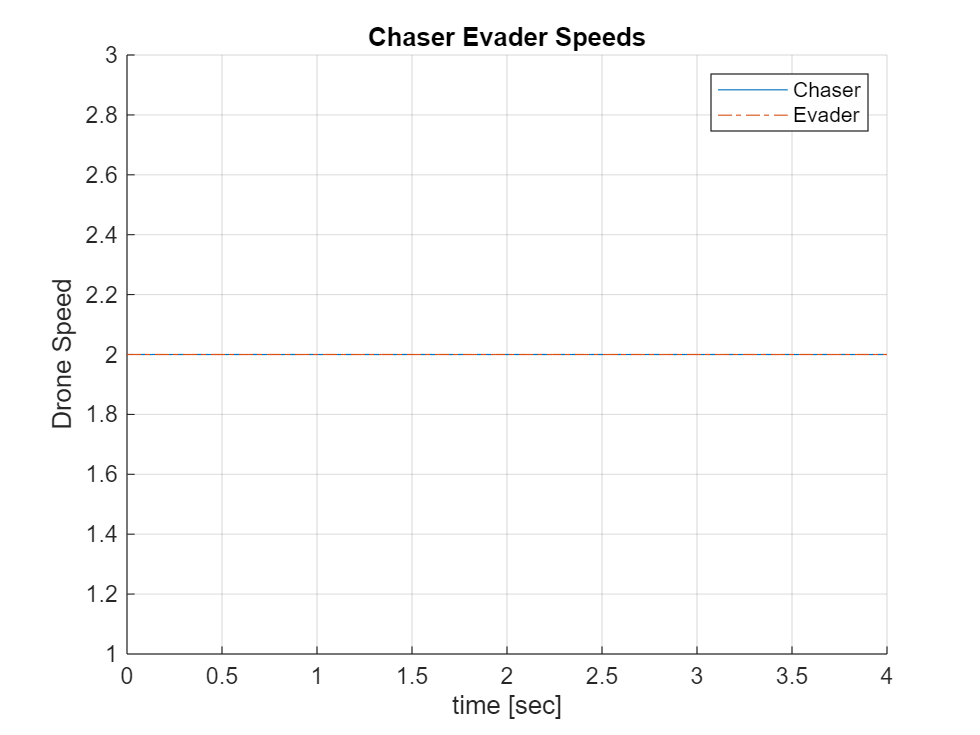

clf; 
hold on; 
grid on; 
plot(tspan, sqrt(y(5, :).^2+y(6, :).^2)); 
plot(tspan, sqrt(y(7, :).^2+y(8, :).^2), "-."); 
title("Chaser Evader Speeds"); 
xlabel("time [sec]"); 
ylabel("Drone Speed"); 
legend("Chaser", "Evader"); 
hold off; 

% nu_history = max([ ...
%         0.5*(sqrt(y(13, :).^2+y(14, :).^2)/maxSpeed-1); ...
%         0.5*(sqrt(y(15, :).^2+y(16, :).^2)/maxSpeed-1)], 0); 
% clf; 
% hold on; 
% grid on; 
% plot(tspan, nu_history(1, :)); 
% plot(tspan, nu_history(2, :), "-."); 
% title("\nu History"); 
% xlabel("time [sec]"); 
% ylabel("\nu"); 
% legend("\nu_1", "\nu_2"); 
% hold off; 
% Differential equations. 
function dydt = eqns(~, y, maxSpeed, areaBnds)
    % Optimal control. 
    % S_1 = (y(13)^2+y(14)^2) < maxSpeed^2; 
    % S_2 = (y(15)^2+y(16)^2) < maxSpeed^2; 
    % u = [ ...
    %     S_1*-y(13) + ~S_1*-maxSpeed*y(13)/sqrt(y(13)^2+y(14)^2); ...
    %     S_1*-y(14) + ~S_1*-maxSpeed*y(14)/sqrt(y(13)^2+y(14)^2); ...
    %     S_2*y(15) + ~S_2*maxSpeed*y(15)/sqrt(y(15)^2+y(16)^2); ...
    %     S_2*y(16) + ~S_2*maxSpeed*y(16)/sqrt(y(15)^2+y(16)^2)]; 
    % nu = max([ ...
    %     0.5*(sqrt(y(13)^2+y(14)^2)/maxSpeed-1); ...
    %     0.5*(sqrt(y(15)^2+y(16)^2)/maxSpeed-1)], 0); 
    % u = [ ...
    %     -y(13)/(1+2*nu(1)); ...
    %     -y(14)/(1+2*nu(1)); ...
    %     -y(15)/(1+2*nu(2)); ...
    %     -y(16)/(1+2*nu(2))]; 

    % Bang-Bang Optimal Control. 
    u = maxSpeed*sign([-y(5:6); y(7:8)]); 

    % Position and velocity constraints. 
    mu = max([ ...
        areaBnds(1)-y(1); ...
        y(1)-areaBnds(2); ...
        areaBnds(3)-y(2); ...
        y(2)-areaBnds(4); ...
        areaBnds(1)-y(3); ...
        y(3)-areaBnds(2); ...
        areaBnds(3)-y(4); ...
        y(4)-areaBnds(4)], 0); 

    A = zeros(4); 
    B = eye(4); 

    % Numerical optimal control. 
    % H = @(u) y(9:16).'*(A*y(1:8)+B*u)+0.5*u.'*u; 
    % options = optimoptions("fmincon", "Display", "off"); 
    % u = fmincon(H, zeros(4, 1), ...
    %     [], [], [], [], -maxSpeed*ones(4, 1), maxSpeed*ones(4, 1), [], options); 

    dydt = [ ...
        A*y(1:4)+B*u; ...
        mu(1)-mu(2); ...
        mu(3)-mu(4); ...
        mu(5)-mu(6); ...
        mu(7)-mu(8)]; 
end

% Boundary conditions. 
function retval = boundaryConditions(y_a, y_b, initialStates)
    retval = [ ...
        y_a(1:4)-initialStates; ...
        y_b(5:8) - [ ...
        y_b(1)-y_b(3); ...
        y_b(2)-y_b(4); ...
        -(y_b(1)-y_b(3)); ...
        -(y_b(2)-y_b(4))]]; 
end

% % fmincon nonlinear constraints. 
% function [c, ceq] = nonlcon(u, maxSpeed)
%     c = [u(1)^2+u(2)^2; u(3)^2+u(4)^2]-maxSpeed^2; 
%     ceq = []; 
% end